## Lecture #2 Lecture Notes - August 27, 2020

## CPE #1 Solution

Create a MATLAB script which return a list of all values (sorted smallest to largest) that appear exactly three times in the input vector **x**. So if

**                x** = [1 2 5 2 2 7 8 3 3 1 3 8 8 8]

then

**                y** = [2 3]

x = [1 2 5 2 2 7 8 3 3 1 3 8 8 8]

x =      1     2     5     2     2     7     8     3     3     1     3     8     8     8


[C,ix,ic] = unique(x)

C =      1     2     3     5     7     8


ix =      1
     2
     8
     3
     6
     7


ic =      1
     2
     4
     2
     2
     5
     6
     3
     3
     1


table = [C;histc(x,C)]

table =      1     2     3     5     7     8
     2     3     3     1     1     4


table(2,:) == 3

ans = 1×6 logical array
   0   1   1   0   0   0


y = C(table(2,:) == 3)

y =      2     3


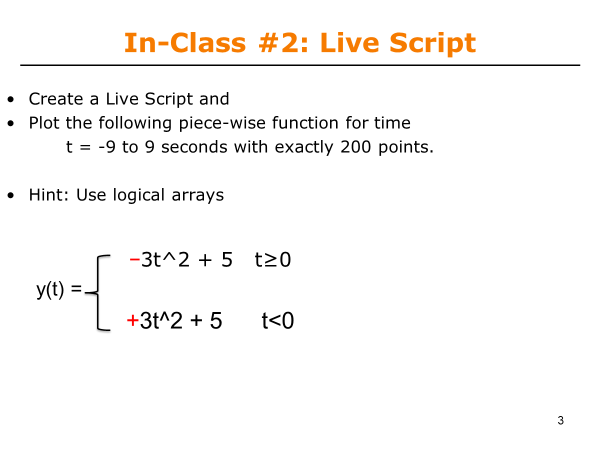

 
t = linspace(-9,9,200);
%create an index using logical arrays
indx = (t>=0)

indx = 1×200 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0



%create your two piecewise function
y1 = -3.*t(indx).^2 + 5     %y(t) for t >= 0 

y1 =     4.9939    4.9448    4.8466    4.6993    4.5030    4.2575    3.9630    3.6194    3.2266    2.7848    2.2939    1.7539    1.1649    0.5267   -0.1606   -0.8969   -1.6823   -2.5169   -3.4005   -4.3332   -5.3150   -6.3458   -7.4258   -8.5549   -9.7330  -10.9603  -12.2366  -13.5620  -14.9365  -16.3601  -17.8328  -19.3546  -20.9255  -22.5454  -24.2145  -25.9326  -27.6999  -29.5162  -31.3816  -33.2961  -35.2597  -37.2723  -39.3341  -41.4450  -43.6049  -45.8139  -48.0721  -50.3793  -52.7356  -55.1410


y2 = 3.*t(~indx).^2 + 5    %y(t) for t < 0 

y2 =   248.0000  243.1401  238.3293  233.5676  228.8550  224.1915  219.5771  215.0117  210.4955  206.0283  201.6103  197.2413  192.9214  188.6506  184.4289  180.2563  176.1327  172.0583  168.0329  164.0567  160.1295  156.2514  152.4224  148.6425  144.9117  141.2300  137.5973  134.0138  130.4793  126.9940  123.5577  120.1705  116.8324  113.5434  110.3035  107.1126  103.9709  100.8783   97.8347   94.8402   91.8949   88.9986   86.1514   83.3532   80.6042   77.9043   75.2535   72.6517   70.0990   67.5955


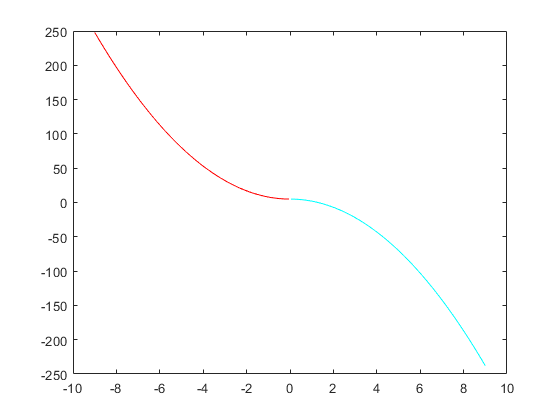

plot(t(~indx),y2,'r',t(indx),y1,'c')

## Cell Array Example

 
MyCell{1} = 'Hello';
MyCell(2) = {'World!'};
MyCell{3} = 5;
MyCell(4) = {[1 2 3 4; 5 6 7 8]};
MyCell      %displays some of the data

MyCell = 1×4 cell array
    {'Hello'}    {'World!'}    {[5]}    {2×4 double}


class(MyCell)

ans = 'cell'

MyCell{4}

ans =      1     2     3     4
     5     6     7     8


MyCell{4}(2,3)   %will return the element

ans = 7

                 %at (2,3) for the array in  	
       		     %the 4th cell of MyCell
celldisp(MyCell) %displays the contents 				     

 
MyCell{1} =
 
Hello
 
 
MyCell{2} =
 
World!
 
 
MyCell{3} =
 
     5

 
 
MyCell{4} =
 
     1     2     3     4
     5     6     7     8

 


                 %of the cell array
MyCell{:}      %displays the contents

ans = 'Hello'

ans = 'World!'

ans = 5

ans =      1     2     3     4
     5     6     7     8
